# KAPITEL 4: Lagrange-Formalismus

## Aufgabe 1


syms l1 l2 g m1 m2 t x1 y1 x2 y2 q1(t) q2(t) T V L

x1 = sin(q1)*l1

$$x1(t) = l_{1}\,\sin\left(q_{1}\left(t\right)\right)$$

y1 = -cos(q1)*l1

$$y1(t) = -l_{1}\,\cos\left(q_{1}\left(t\right)\right)$$


x2 = x1 + sin(q2)*l2

$$x2(t) = l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)$$

y2 = y1 - cos(q2)*l2

$$y2(t) = -l_{1}\,\cos\left(q_{1}\left(t\right)\right)-l_{2}\,\cos\left(q_{2}\left(t\right)\right)$$

## Aufgabe 2

u1 = diff(x1,t)

$$u1(t) = l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)$$

v1 = diff(y1,t)

$$v1(t) = l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)$$

u1_g = sqrt(u1^2+v1^2)

$$u1\_g(t) = \sqrt{{l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}$$


u2 = diff(x2,t)

$$u2(t) = l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)$$

v2 = diff(y2,t)

$$v2(t) = l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)$$

u2_g = sqrt(u2^2+v2^2)

$$u2\_g(t) = \sqrt{{\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}$$

## Aufgabe 3


F_kin1 = 1/2 * m1 * u1_g^2

$$F\_kin1(t) = \frac{m_{1}\,\left({l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\right)}{2}$$

F_kin2 = 1/2 * m2 * u2_g^2

$$F\_kin2(t) = \frac{m_{2}\,\left({\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}\right)}{2}$$

T = F_kin1 + F_kin2

$$T(t) = \begin{array}{l} \frac{m_{2}\,\left({\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{1}\,\left({l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{1}+{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{1}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$


F_pot1 = m1 * g * y1

$$F\_pot1(t) = -g\,l_{1}\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)$$

F_pot2 = m2 * g * y2

$$F\_pot2(t) = -g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\right)$$

V = F_pot1 + F_pot2

$$V(t) = -g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\right)-g\,l_{1}\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)$$

## Aufgabe 4

L = T - V

$$L(t) = \begin{array}{l} \frac{m_{2}\,\left({\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{1}\,\left({l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{1}+{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{1}\right)}{2}+g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2} \end{array}$$

## Aufgabe 5

syms q1_d q2_d q1_dd q2_dd q1t q2t

D(1) = diff(L,diff(q1,t))

D(2) = diff(L,diff(q2,t))

$$D = \begin{array}{l} \left(\begin{array}{cccc} \frac{m_{1}\,\left(2\,{l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)+2\,{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}+\frac{m_{2}\,\left(2\,l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{2}+2\,l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\sigma_{1}\right)}{2} & \frac{m_{2}\,\left(2\,l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{2}+2\,l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\sigma_{1}\right)}{2} & -\frac{m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)-2\,l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}-g\,l_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\sin\left(q_{1}\left(t\right)\right) & -\frac{m_{2}\,\left(2\,l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)-2\,l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}{2}-g\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}$$

D(3) = diff(L,q1)

$$D = \begin{array}{l} \left(\begin{array}{cccc} \frac{m_{1}\,\left(2\,{l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)+2\,{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}+\frac{m_{2}\,\left(2\,l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{2}+2\,l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\sigma_{1}\right)}{2} & \frac{m_{2}\,\left(2\,l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{2}+2\,l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\sigma_{1}\right)}{2} & -\frac{m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)-2\,l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}-g\,l_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\sin\left(q_{1}\left(t\right)\right) & -\frac{m_{2}\,\left(2\,l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)-2\,l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}{2}-g\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}$$

D(4) = diff(L,q2)

$$D = \begin{array}{l} \left(\begin{array}{cccc} \frac{m_{1}\,\left(2\,{l_{1}}^{2}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)+2\,{l_{1}}^{2}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}+\frac{m_{2}\,\left(2\,l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{2}+2\,l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\sigma_{1}\right)}{2} & \frac{m_{2}\,\left(2\,l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{2}+2\,l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\sigma_{1}\right)}{2} & -\frac{m_{2}\,\left(2\,l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)-2\,l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}-g\,l_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\sin\left(q_{1}\left(t\right)\right) & -\frac{m_{2}\,\left(2\,l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\sigma_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)-2\,l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}{2}-g\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}$$


D(1) = diff(D(1),t)

D(2) = diff(D(2),t)


D = subs(D,[diff(q1,t,2) diff(q2,t,2)], [q1_dd q2_dd])


Q1 = simplify(D(1) - D(3))

$$Q1 = {l_{1}}^{2}\,m_{1}\,q_{1,\mathrm{dd}}+{l_{1}}^{2}\,m_{2}\,q_{1,\mathrm{dd}}+g\,l_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)+g\,l_{1}\,m_{2}\,\sin\left(q_{1}\left(t\right)\right)+l_{1}\,l_{2}\,m_{2}\,q_{2,\mathrm{dd}}\,\cos\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)+l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}$$

Q2 = simplify(D(2) - D(4))

$$Q2 = {l_{2}}^{2}\,m_{2}\,q_{2,\mathrm{dd}}+g\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)+l_{1}\,l_{2}\,m_{2}\,q_{1,\mathrm{dd}}\,\cos\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)-l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}$$


q1_pp = solve(Q1==0,q1_dd)

$$q1\_pp = -\frac{l_{2}\,m_{2}\,\sin\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+g\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)+g\,m_{2}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,m_{2}\,q_{2,\mathrm{dd}}\,\cos\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)}{l_{1}\,m_{1}+l_{1}\,m_{2}}$$


q2_pp = solve(Q2==0,q2_dd)

$$q2\_pp = -\frac{-l_{1}\,\sin\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+g\,\sin\left(q_{2}\left(t\right)\right)+l_{1}\,q_{1,\mathrm{dd}}\,\cos\left(q_{1}\left(t\right)-q_{2}\left(t\right)\right)}{l_{2}}$$

## Aufgabe 6

l1 = 1;

l1 = 1

l2 = 2;

l2 = 2

m1 = 0.5;

m1 = 0.5000

m2 = 1;

m2 = 1

g = 9.81;

g = 9.8100

## Aufgabe 10

epsilon = eps 

epsilon = 2.2204e-16

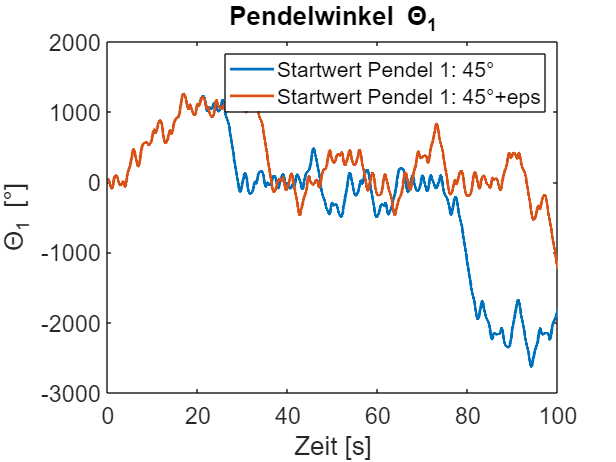

verlauf1 = load('verlauf1.mat');
verlauf2 = load('verlauf2.mat');
verlauf1 = verlauf1.verlauf1;
verlauf2 = verlauf2.verlauf2;

t = linspace(0,100,10001);

figure;
plot(t,verlauf1(:,1)/pi*180), hold on
plot(t,verlauf2(:,1)/pi*180),
legend('Startwert Pendel 1: 45°', 'Startwert Pendel 1: 45°+eps');
xlabel('Zeit [s]');
ylabel('\Theta_1 [°]');
title('Pendelwinkel \Theta_1');
hold off

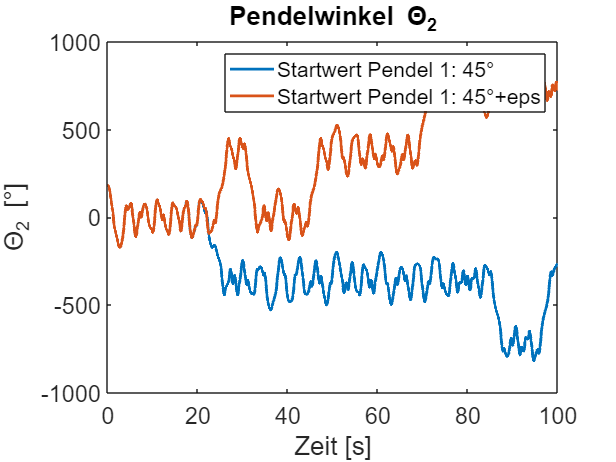


figure;
plot(t,verlauf1(:,2)/pi*180), hold on
plot(t,verlauf2(:,2)/pi*180),
legend('Startwert Pendel 1: 45°', 'Startwert Pendel 1: 45°+eps');
xlabel('Zeit [s]');
ylabel('\Theta_2 [°]');
title('Pendelwinkel \Theta_2');
hold off